## **Курсовой проект**

## **По дисциплине: Моделирование и управление движением Роботов**

## **Тема:**

## **Планирование траекторий и управление движением робота-манипулятора при сварке изделий на производстве**

## **Авторы:**

**Соболев А.**

**Ису: **

**Коротков А.А.**

**Ису: **369910

Был произведен анализ роботов манипуляторв, представленных на рынке. Был произведен выбор робота манипулятора по ряду сравнительных харрактеристик:

Робот манипулятор Motoman HP6 имеет ряд преимуществ для сварки, среди которых:

- Высокая точность и повторяемость: Благодаря своей точности и повторяемости, Motoman HP6 может обеспечить точность перемещения торчка сварочной головки и отличную сварочную точность, что в свою очередь дает более высококачественное сварочное соединение.

- Большая грузоподъемность: Motoman HP6 имеет грузоподъемность до 6 кг, что позволяет роботу манипулировать сварочными материалами и другими инструментами и оборудованием большого размера и веса.

- Надежность и долговечность: Робот-сварщик Motoman HP6, оснащенный высококачественными компонентами и инновационным программным обеспечением, обеспечивает высокую надежность и долговечность в работе. Он требует минимального обслуживания и ремонта, что позволяет снизить общую стоимость владения и эксплуатации робота манипулятора для сварки.

## Задание параметров робота

Воспользуемся документацией, которую предоставляет компания YASKAWA, чтобы определить параметры робота MOTOMAN-HP6.

На своем борту робот имеет 6 звеньев со своими приводами (ниже модели двигателей для каждого привода)

- SGMRS-06A2B-YR1

- SGMRS-12A2B-YR1

- SGMRS-06A2B-YR1

- SGMPH-01A2A-YR1

- SGMPH-01A2A-YR1

- SGMPH-01A2A-YR1

Чтобы производить дальнейшие вычисления зададим необходимые для расчетов параметры:

- Массы звеньев

- Центры масс звеньев

- Моменты инерции звеньев

- Ограничения приводов на поворот

- Моменты инерции валов двигателей

- Передаточные числа редукторов

- Вязкое трение двигателя

clear;
clc;
close all

% Выгрузка модели робота
mdl_motomanHP6;


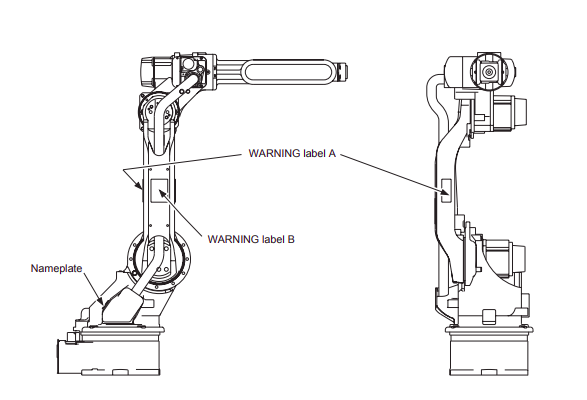

% Позиции старта и конца
qp_start = [0 0 0 0 0 0];
qp_end = [45 -82.5 67.5 113 -45 30];
qp_dest = deg2rad(qp_end)

qp_dest =     0.7854   -1.4399    1.1781    1.9722   -0.7854    0.5236



% Задание масс звеньев
hp6.links(1,1).m = 46;
hp6.links(1,2).m = 40;
hp6.links(1,3).m = 27;
hp6.links(1,4).m = 27;
hp6.links(1,5).m = 7;
hp6.links(1,6).m = 3;

% Центры масс звеньев
hp6.links(1,1).r = [hp6.links(1,1).a/2, 0, 0];
hp6.links(1,2).r = [hp6.links(1,2).a/2, 0, 0];
hp6.links(1,3).r = [hp6.links(1,3).a/2, 0, 0];
hp6.links(1,4).r = [0, 0, hp6.links(1,4).d/2];
hp6.links(1,5).r = [0 0 0];
hp6.links(1,6).r = [0, 0, hp6.links(1,6).d/2];

% Расчет моментов инерции

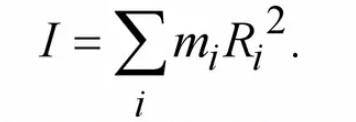

% 1,2,3 звенья
J_link = zeros(3,3);
for i = 1:1:3
    % Jxx
    J_link(1,1) = hp6.links(1,i).m * hp6.links(1,i).a^2 / 3;
    % Jyy
    J_link(2,2) = hp6.links(1,i).m * hp6.links(1,i).a^2 / 3;
    % Jzz
    J_link(3,3) = hp6.links(1,i).m * hp6.links(1,i).a^2 / 3;

    hp6.links(1,i).I = J_link;
end
% 4,5,6 звенья
for i = 4:1:6
    % Jxx
    J_link(1,1) = hp6.links(1,i).m * hp6.links(1,i).a^2 / 3;
    % Jyy
    J_link(2,2) = hp6.links(1,i).m * hp6.links(1,i).a^2 / 3;
    % Jzz
    J_link(3,3) = hp6.links(1,i).m * hp6.links(1,i).a^2 / 3;

    hp6.links(1,i).I = J_link;
end

% Ограничения приводов на поворот
limits = deg2rad([-170,170; ...
                  -90,155; ...
                  -175,250; ...
                  -180,180; ...
                  -45,225; ...
                  -360,360]);
% Ограничения для каждого звена
for i = 1:1:6
    hp6.qlim(i,1) = limits(i,1);
    hp6.qlim(i,2) = limits(i,2);
end

% Моменты инерции валов двигателелей
hp6.links(1,1).Jm = 0.000325;
hp6.links(1,2).Jm = 0.000105;
hp6.links(1,3).Jm = 0.000033;
hp6.links(1,4).Jm = 0.000019;
hp6.links(1,5).Jm = 0.000019;
hp6.links(1,6).Jm = 0.000019;

% Передаточные числа
hp6.links(1,1).G = 327;
hp6.links(1,2).G = 327;
hp6.links(1,3).G = 327;
hp6.links(1,4).G = 200;
hp6.links(1,5).G = 200;
hp6.links(1,6).G = 200;

% Вязкое трение
hp6.links(1,1).B = 0;
hp6.links(1,2).B = 0;
hp6.links(1,3).B = 0;
hp6.links(1,4).B = 0;
hp6.links(1,5).B = 0;
hp6.links(1,6).B = 0;

% номинальный момент двигателя для каждого звена
torq_const(1) = 0.64; 
torq_const(2) = 1.83; 
torq_const(3) = 0.64;  
torq_const(4) = 0.1; 
torq_const(5) = 0.1; 
torq_const(6) = 0.1; 

% максимальный момент для каждого звена
torq_max(1) = 2; 
torq_max(2) = 5.5; 
torq_max(3) = 2;  
torq_max(4) = 0.32; 
torq_max(5) = 0.32;
torq_max(6) = 0.32;

## Решение обратной задачи динамики

close all

**Планирование траектории**

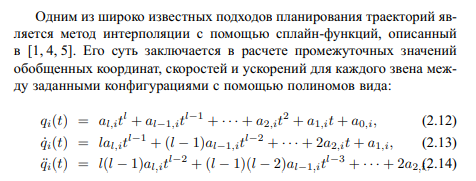

**jtraj** используется для генерации траектории движения точки между двумя заданными точками, где скорость и ускорение равны нулю на обоих концах траектории. Она генерирует траекторию плавной скорости, называемую трапециевидной скоростью, которая представляет собой постоянную скорость в середине траектории и равномерное замедление в начале и конце.

[qp, qp_d, qp_dd] = jtraj(qp_start, qp_dest, 100);

## Метод Ньютона-Эйлера

Вывод уравнений движения на основе метода Ньютона-Эйлера представляет собой рекурсивную процедуру, которая для 𝑛-звенного манипулятора последовательной кинематики может быть разбита на следующие шаги: 

1. Инициализация. ∙ Определить количество тип каждого звена: призматическое или вращательное. ∙ Выбрать системы координат 𝑂𝑖𝑥𝑖𝑦𝑖𝑧𝑖 для 𝑖 = 0, . . . , 𝑛 где 𝑖-ая система координат прикреплена к звену 𝑖, а система координат с индексом 0 является инерциальной. Например, на основании соглашения Денавита-Хартенберга (см. Приложение 2). ∙ Определить соответствующие геометрические параметры, входящие в выражения для матриц однородных преобразований, задающих взаимное расположение соседних систем координат. ∙ Определить динамические параметры робота: масса, тензор инерции и координаты центра масс для каждого звена, на основе которых также должны быть вычислены координаты радиус-векторов 𝑟𝑖−1,𝑐𝑖 и 𝑟𝑖,𝑐𝑖 . ∙ Задать начальные значения линейных и угловых скоростей и ускорений базы робота. ∙ Задать начальные значения внешних сил и моментов, приложенных к терминальному звену робота.

2. Прямая рекурсия. Вычислить линейные и угловые скорости и ускорения звеньев робота последовательно от 1-го до 𝑛-го. 3.2 Вывод уравнений движения на основе метода Ньютона-Эйлера63 

3. Обратная рекурсия. Вычислить силы и моменты, действующие на звенья робота последовательно от 𝑛-го до 1-го, стартуя с терминальных условий на 𝑓𝑛+1 и 𝜏𝑛+1.

Qp = hp6.rne(qp, qp_d, qp_dd);
Qp0 = hp6.rne(qp, zeros(100, 6), zeros(100, 6)); %силы для удерживания манипулятора на весу без движения
Gp = hp6.gravload(qp) %Силы тяжести

Gp =     0.0000 -811.2134  117.8426         0         0         0
    0.0000 -811.2179  117.8471   -0.0022    0.0000   -0.0000
    0.0000 -811.2486  117.8778   -0.0176    0.0002   -0.0000
   -0.0000 -811.3303  117.9596   -0.0585    0.0007   -0.0000
   -0.0000 -811.4860  118.1155   -0.1366    0.0016   -0.0000
   -0.0000 -811.7367  118.3670   -0.2626    0.0031   -0.0000
   -0.0000 -812.1016  118.7338   -0.4466    0.0052   -0.0000
   -0.0000 -812.5976  119.2340   -0.6980    0.0081   -0.0000
    0.0000 -813.2390  119.8838   -1.0254    0.0119   -0.0000
    0.0000 -814.0378  120.6976   -1.4366    0.0167   -0.0000


Mp = hp6.inertia(qp) %Матрицы нагрузок (масс)

Mp = Mp(:,:,1) =

  137.9207    5.4435   -5.4435    2.7218   -0.0000    0.0000
    5.4435   96.9601  -24.5189    5.4435   -0.0973    0.0000
   -5.4435  -24.5189   21.2004   -5.4435    0.0973   -0.0000
    2.7218    5.4435   -5.4435    3.4818   -0.0000    0.0000
   -0.0000   -0.0973    0.0973   -0.0000    0.7668   -0.0000
    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.7600


Mp(:,:,2) =

  137.9215    5.4434   -5.4435    2.7216    0.0000   -0.0000
    5.4434   96.9602  -24.5189    5.4436   -0.0973    0.0000
   -5.4435  -24.5189   21.2003   -5.4435    0.0973   -0.0000
    2.7216    5.4436   -5.4435    3.4818   -0.0000    0.0000
    0.0000   -0.0973    0.0973   -0.0000    0.7668   -0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.7600


Mp(:,:,3) =

  137.9270    5.4427   -5.4433    2.7206    0.0000   -0.0000
    5.4427   96.9607  -24.5189    5.4440   -0.0973    0.0000
   -5.4433  -24.5189   21.2000   -5.4435    0.0973   -0.0000
    2.7206    5.4440   -5.4435    3.4

Cp = hp6.coriolis(qp, qp_d)

Cp = Cp(:,:,1) =

     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Cp(:,:,2) =

    0.1177   -0.0803    0.0592   -0.0623    0.0010    0.0000
    0.0487    0.0106   -0.0688    0.0488   -0.0006   -0.0000
   -0.0487    0.0661   -0.0079   -0.0104    0.0001    0.0000
    0.0177   -0.0315    0.0104    0.0000   -0.0000    0.0000
   -0.0003    0.0005   -0.0002    0.0000    0.0000    0.0000
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000


Cp(:,:,3) =

    0.4613   -0.3145    0.2318   -0.2443    0.0040    0.0000
    0.1908    0.0415   -0.2696    0.1912   -0.0022   -0.0000
   -0.1909    0.2590   -0.0310   -0.0408    0.0005    0.0000
    0.0692   -0.1236    0.0409    0.0000   -0.0000    0.0000
   -0.0012    0.0021   -0.0007    0.0000    0.0000    0.0000
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.000

figure;
hold on;
grid on;
subplot (6,1,1)
plot(Qp(:,1))
hold on
plot(Qp0(:,1))
title("Звено 1")
xlabel('t [s]');
hold off;
subplot (6,1,2)
plot(Qp(:,2))
hold on
plot(Qp0(:,2))
title("Звено 2")
xlabel('t [s]');
hold off;
subplot (6,1,3)
plot(Qp(:,3))
hold on
plot(Qp0(:,3))
title("Звено 3")
xlabel('t [s]');
hold off;
subplot (6,1,4)
plot(Qp(:,4))
hold on
plot(Qp0(:,4))
title("Звено 4")
xlabel('t [s]');
hold off;
subplot (6,1,5)
plot(Qp(:,5))
hold on
plot(Qp0(:,5))
title("Звено 5")
xlabel('t[s]');
hold off;
subplot (6,1,6)
plot(Qp(:,6))
hold on
plot(Qp0(:,6))
title("Звено 6")
xlabel('t[s]');
hold off;


Звенья меняют свое положение относительно трех координат, поэтому данный график меняется.

Были введены параметры робота, вычислены инерциальные параметры. Так же была решена задача обратной динамики, были выведены матрицы масс  M, вектор кориолисовых и центробежных сил C и вектор гравитационных  сил G.

## **Построение рабочей зоны манипулятора**

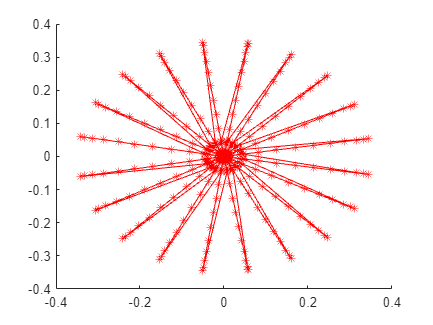

close all
N=20; % Количество точек
ki=1; % Счетчик
lim=hp6.qlim; 
pose=zeros(3,N^3);
for q1=linspace(lim(1,1),lim(1,2),N) % Ограничения для 1 звена
    for q2=linspace(lim(2,1),lim(2,2),N) % Ограничения для 2 звена
          for q3=linspace(lim(3,1),lim(3,2),N) % Ограничения для 3 звена
            q=[q1,q2,q3,0,0,0];  % Вектор обобщенных координат
             p0=hp6.fkine(q); % Прямая задача кинематики
             p0=p0.t; % Положение инструмента
        end
        pose(:,ki)=p0; % Записываем положения
        ki=ki+1;
    end
end

line(pose(1,:),pose(2,:),pose(3,:), 'Color',[1 0 0], 'Marker','*') % Рисунок рабочей зоны

plot(pose);

## Планирование движения, Задание начальных и конечных представлений

close all
q1=[0,0,0,0,0,pi]; %% Начальное положение 
T1 = transl(0.5, 0.2, 0.3) * trotx(pi/2) %% задаём конечное положение эндэффектора и (перевод из операционного пространства)

T1 =     1.0000         0         0    0.5000
         0    0.9996   -0.0274    0.2000
         0    0.0274    0.9996    0.3000
         0         0         0    1.0000


q2 = hp6.ikine(T1, q1, 'mask', [1 1 1 0 0 0])

q2 =     0.3799   -2.1784   -1.0036   -0.0098   -0.3726         0


%q2 = [0.1 0.2 0.3 0.4 0.5 0.6] % можно задать вручную таким образом 
t = [0:0.05:2]'; % Интервал времени
[q,qd,qdd] = jtraj(q1, q2, t);  % Положение, скорость, ускорение



1 способ

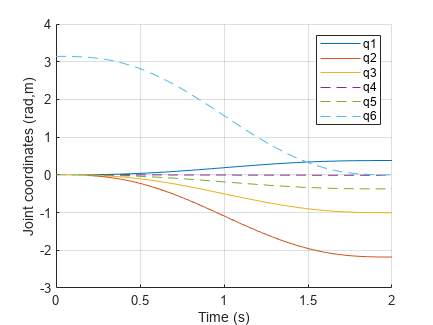

figure
q = jtraj(q1, q2, t);
qplot(t,q)

2 способ

path = [q1; q2];

**mstraj -** используется для генерации сложных траекторий движения, которые содержат изменения скорости и ускорения в течение траектории. Она генерирует плавный профиль скорости и ускорения, который может быть настроен по многим параметрам, таким как начальная и конечная скорость, максимальная скорость, максимальное ускорение и т. д.

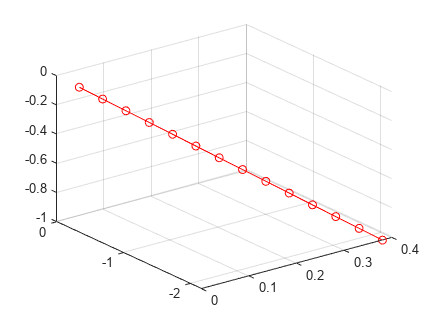

p = mstraj(path, [0.25 0.25 0.2 0.25 0.25 0.25], [], [], 1, 0.2);
figure
plot3(p(:,1),p(:,2),p(:,3), 'or-', "MarkerSize", 6); grid on

Отобразим базовое передвижение по линии

BaseMotion

## Рассчитаем инерцию каждого звена манипулятора

chislotochek = 5; % Задаем число точек для расчета матриц масс

% Задаем сетки и пустые массивы для дальнейших расчетов
QQ2 = linspace(hp6.qlim(2,1),hp6.qlim(2,2),chislotochek);
QQ3 = linspace(hp6.qlim(3,1),hp6.qlim(3,2),chislotochek);
QQ4 = linspace(hp6.qlim(4,1),hp6.qlim(4,2),chislotochek);
M11bez = zeros(chislotochek,chislotochek); M22bez = zeros(chislotochek,chislotochek);
M33bez = zeros(chislotochek,chislotochek); M44bez = zeros(chislotochek,chislotochek);
M55bez = zeros(chislotochek,chislotochek); M66bez = zeros(chislotochek,chislotochek);
[Q2,Q3,Q4] = meshgrid(QQ2, QQ3, QQ4);



**Матрица масс** представляет собой симметричную матрицу *M,* которая выражает связь между производной по времени вектора обобщенных координат *q* системы и кинетической энергией *T* этой системы по уравнению

% Определяем возможные значения матрицы масс вдоль заданной траектории для каждого звена 
for i=1:numcols(Q2)
    for j=1:numcols(Q3)
        for k=1:numcols(Q4)
            Mbez = hp6.inertia([0, Q2(i,j,k), Q3(i,j,k), Q4(i,j,k), 0, 0]);
            M11bez(j,k) = Mbez(1,1);
            M22bez(j,k) = Mbez(2,2);
            M33bez(j,k) = Mbez(3,3);
            M44bez(j,k) = Mbez(4,4);
            M55bez(j,k) = Mbez(5,5);
            M66bez(j,k) = Mbez(6,6);
        end    
    end
end

% Находим средние значения матриц масс для каждого звена
Meanbez(1) = mean(M11bez,'all');
Meanbez(2) = mean(M22bez,'all');
Meanbez(3) = mean(M33bez,'all');
Meanbez(4) = mean(M44bez,'all');
Meanbez(5) = mean(M55bez,'all');
Meanbez(6) = mean(M66bez,'all');


% Определим отношение максимального и минимального элементов
% матриц масс при движении вдоль заданной траектории
otnbez = zeros(1,6);
otnbez(1) = max(M11bez(:))/min(M11bez(:));
otnbez(2) = max(M22bez(:))/min(M22bez(:));
otnbez(3) = max(M33bez(:))/min(M33bez(:));
otnbez(4) = max(M44bez(:))/min(M44bez(:));
otnbez(5) = max(M55bez(:))/min(M55bez(:));
otnbez(6) = max(M66bez(:))/min(M66bez(:));
otnbez

otnbez =     2.0766    1.0640    1.2537    1.0000    1.0000    1.0000



% Вычисляем инерцию каждого звена
InertiaA = zeros(1,6);
for i=1:6
    InertiaA(i) = hp6.links(1,i).Jm + Meanbez(i)/(hp6.links(1,i).G^2)
end

InertiaA = 1.0e-03 *

    0.9449         0         0         0         0         0


InertiaA = 1.0e-03 *

    0.9449    0.6133         0         0         0         0


InertiaA = 1.0e-03 *

    0.9449    0.6133    0.2414         0         0         0


InertiaA = 1.0e-03 *

    0.9449    0.6133    0.2414    0.1060         0         0


InertiaA = 1.0e-03 *

    0.9449    0.6133    0.2414    0.1060    0.0382         0


InertiaA = 1.0e-03 *

    0.9449    0.6133    0.2414    0.1060    0.0382    0.0380


### Настроим генератор траектории


q_start = [0,0,0,0,0,pi] % Задаем начальное положение робота

q_start =          0         0         0         0         0    3.1416


point = [0.5,0.5,0.5]; % Выбираем конечную точку из рабочего пространства робота
T1 = transl(0.5, 0.2, 0.3) * trotx(pi/2) %% задаём конечное положение эндэффектора и (перевод из операционного пространства)

T1 =     1.0000         0         0    0.5000
         0    0.9996   -0.0274    0.2000
         0    0.0274    0.9996    0.3000
         0         0         0    1.0000


q_end = hp6.ikine(T1, q1, 'mask', [1 1 1 0 0 0])

q_end =     0.3799   -2.1784   -1.0036   -0.0098   -0.3726         0


stop_time = 5; % Задаем время симуляции

#### Настроим контуры управления по скорости и положению без нагрузки

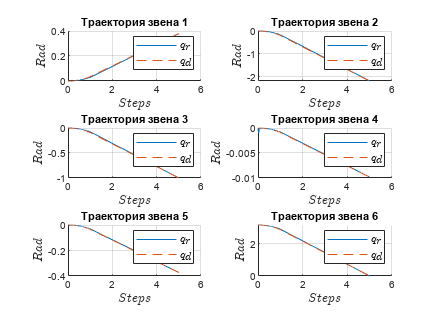

% vloop_no_load % Запускаем контур управления по скорости
ploop_no_load % Запускаем контур управления по положению

NL = sim("ploop_no_load.slx"); % Выполняем симуляцию

% Построим графики реальной (r) траектории движения и желаемой (d) для каждого звена
figure; 
for i=1:1:6
    subplot(3,2,i)
    hold on
    plot(NL.THETA.time, NL.THETA.data(:,i), NL.Q.time, NL.Q.data(:,i), '--')
    grid on
    legend('$q_r$', '$q_d$', 'fontsize', 9,'interpreter','latex');
    ylabel('$Rad$', 'fontsize', 10, 'interpreter', 'latex');
    xlabel('$Steps$', 'fontsize', 10, 'interpreter', 'latex');
    title(['Траектория звена ', num2str(i)]);
end

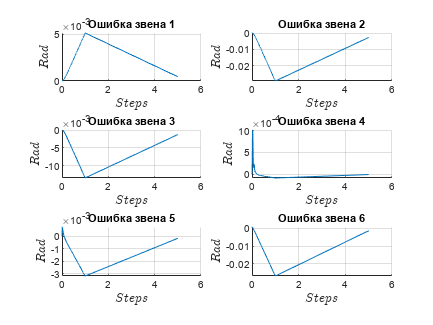


figure; % Построим графики ошибок для каждого звена
for i=1:1:6
    subplot(3,2,i)
    hold on
    plot(NL.ERR.time, NL.ERR.data(:,i))
    grid on
    ylabel('$Rad$', 'fontsize', 10, 'interpreter', 'latex');
    xlabel('$Steps$', 'fontsize', 10, 'interpreter', 'latex');
    title(['Ошибка звена ', num2str(i)]);
end

#### Добавим нагрузку и пересчитаем инерцию каждого звена 

hp6.payload(5,[0,0,0.1]); % Добавляем нагрузку 5 кг 

% Задаем пустые массивы для дальнейших вычислений
M11s = zeros(chislotochek,chislotochek); M22s = zeros(chislotochek,chislotochek);
M33s = zeros(chislotochek,chislotochek); M44s = zeros(chislotochek,chislotochek);
M55s = zeros(chislotochek,chislotochek); M66s = zeros(chislotochek,chislotochek);

% Определяем возможные значения матрицы масс вдоль заданной траектории для каждоого звена 
for i=1:numcols(Q2)
    for j=1:numcols(Q3)
        for k=1:numcols(Q4)
            Ms = hp6.inertia([0, Q2(i,j,k), Q3(i,j,k), Q4(i,j,k), 0, 0]);
            M11s(j,k) = Ms(1,1);
            M22s(j,k) = Ms(2,2);
            M33s(j,k) = Ms(3,3);
            M44s(j,k) = Ms(4,4);
            M55s(j,k) = Ms(5,5);
            M66s(j,k) = Ms(6,6);
        end    
    end
end

% Находим средние значения матриц масс для каждого звена
Means(1) = mean(M11s,'all');
Means(2) = mean(M22s,'all');
Means(3) = mean(M33s,'all');
Means(4) = mean(M44s,'all');
Means(5) = mean(M55s,'all');
Means(6) = mean(M66s,'all');

% Вычисляем инерцию каждого звена
InertiaS = zeros(1,6);
for i=1:6
    InertiaS(i) = hp6.links(1,i).Jm + Means(i)/(hp6.links(1,i).G^2)
end

InertiaS = 1.0e-03 *

    0.9469         0         0         0         0         0


InertiaS = 1.0e-03 *

    0.9469    0.6168         0         0         0         0


InertiaS = 1.0e-03 *

    0.9469    0.6168    0.2610         0         0         0


InertiaS = 1.0e-03 *

    0.9469    0.6168    0.2610    0.1060         0         0


InertiaS = 1.0e-03 *

    0.9469    0.6168    0.2610    0.1060    0.0428         0


InertiaS = 1.0e-03 *

    0.9469    0.6168    0.2610    0.1060    0.0428    0.0380


% Определим отношение максимального и минимального элементов
% матриц масс при движении вдоль заданной траектории
otn(1) = max(M11s(:))/min(M11s(:));
otn(2) = max(M22s(:))/min(M22s(:));
otn(3) = max(M33s(:))/min(M33s(:));
otn(4) = max(M44s(:))/min(M44s(:));
otn(5) = max(M55s(:))/min(M55s(:));
otn(6) = max(M66s(:))/min(M66s(:));
otn

otn =     2.0655    1.0635    1.2309    1.0000    1.0000    1.0000


### Перенастроим контуры управления по скорости и положению

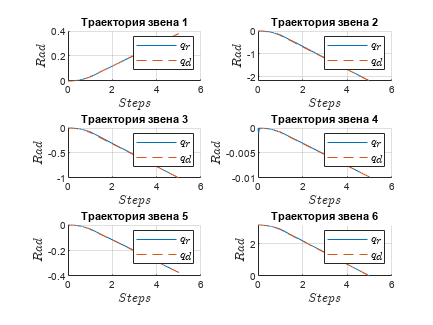

% vloop_load % Запускаем контур управления по скорости
ploop_load % Запускаем контур управления по положению

WL = sim("ploop_load.slx"); % Выполняем симуляцию

% Построим графики реальной (r) траектории движения и желаемой (d) для каждого звена
figure; 
for i=1:1:6
    subplot(3,2,i)
    hold on
    plot(WL.THETA.time, WL.THETA.data(:,i), WL.Q.time, WL.Q.data(:,i), '--')
    grid on
    legend('$q_r$', '$q_d$', 'fontsize', 9,'interpreter','latex');
    ylabel('$Rad$', 'fontsize', 10, 'interpreter', 'latex');
    xlabel('$Steps$', 'fontsize', 10, 'interpreter', 'latex');
    title(['Траектория звена ', num2str(i)]);
end

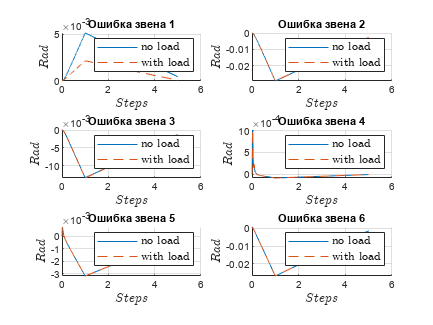


figure; % Сравним графики ошибок для каждого звена
for i=1:1:6
    subplot(3,2,i)
    hold on
    plot(NL.ERR.time, NL.ERR.data(:,i), WL.ERR.time, WL.ERR.data(:,i), '--')
    grid on
    legend('no load', 'with load', 'fontsize', 9,'interpreter','latex');
    ylabel('$Rad$', 'fontsize', 10, 'interpreter', 'latex');
    xlabel('$Steps$', 'fontsize', 10, 'interpreter', 'latex');
    title(['Ошибка звена ', num2str(i)]);
end

## Моделирование управления

Для управления роботом необходимо задать траекторию движения. Для этого используется функция mstraj - она позволяет задать кусочно определенную функцию.

Траектория будет представлять из себя набор точек, на котором можно выделить 3 основных участка:

- Установка сварочной головки на начало сварного шва

- Движение вдоль сварного шва

- Возвращение на исходную позицию

Такое построение траектории позволяет решать задачи сварки на большинстве производств в условиях определенного рабочего пространства с заранее определенным положением свариваемых деталей.

*Примечание к модели: параметр ****n_points**** определяет кол-во промежуточных точек на прямом сварочном участке*

% Создание траектории
n_points = 20;

point_start = zeros(n_points+1, 6);
point_end = zeros(n_points+1, 6);

% Установка сварочной головки на начало сварного шва
q_start_1 = hp6.ikine(transl(0.875, 0, -0.730), [0,0], 'mask',[1 1 1 0 0 0]);
q_end_1 =   hp6.ikine(transl(0.9,   1, -0.1),   [0,0], 'mask',[1 1 1 0 0 0]);
point_start(1,:) = q_start_1(1, :);
point_end(1,:) = q_end_1(1, :);


% Движение вдоль сварного шва
for i = 1:1:(n_points)
    y_val_start = 1 - 2*(i/n_points);
    y_val_end = 1 - 2*(i/(n_points+1));

    q_start_w = hp6.ikine(transl(0.9, y_val_start, -0.1), [0,0], 'mask',[1 1 1 0 0 0]);
    q_end_w =   hp6.ikine(transl(0.9, y_val_end,   -0.1), [0,0], 'mask',[1 1 1 0 0 0]);

    point_start(i+1,:) = q_start_w(1,:);
    point_end(i+1,:) = q_end_w(1,:);
end

% Возвращение на исходную позицию
point_start(n_points+1,:) = point_end(n_points-1,:);
point_end(n_points+1,:) = point_start(1,:);

% Объединение траекторий
pathFull2 = [point_start(1,:); point_end(1,:)];
for i = 2:1:(n_points)
    pathFull2 = cat(1,pathFull2,[point_start(i,:); point_end(i,:)]);
end

### Построение траектории

vel = 0.1; % скорость
acc = 0.2; % ускорение

q_traj = mstraj(pathFull2, [1 1 1 1 1 1], [],[], vel, acc); % траектория

K = {'r', 'LineWidth', 2};
%subplot(2,2,2); 
%hp6.plot(pathFull2, 'trail', K); 
% hp6.plot(q_traj, 'trail', K);
hp6.plot(q_traj, 'trail', K);

### Графики положения звеньев

figure
hold on
grid on
plot(q_traj, "LineWidth", 2);
legend('q1','q2','q3','q4','q5','q6', 'fontsize',12, 'interpreter','latex');
ylabel('q', 'fontsize',12,'interpreter','latex');
xlabel('time', 'fontsize',12,'interpreter','latex');

Видно, что графики положения звеньев имеет пилообразный вид - это связанно с тем, что траектория задана кусочно. Амплитуду колебаний можно изменять варьируя параметр ***n_points****.*

### Реализация управления

#### FeedForward control

Управление с прямой связью работает по следующему принципу: результирующий сигнал управления состоит из 2-х частей:

- $M\left(q^* \right){\ddot{q} }^* +C\left(q^* ,{\dot{q} }^* \right){\dot{q} }^* +F\left({\dot{q} }^* \right)+G\left(q^* \right)$, **Прямая связь** - это расчет усилий в приводах необходимых роботу для того, чтобы находиться в заданном положении

- $K_v \left({\dot{q} }^* -{\dot{q} }^# \right)+K_p \left(q^* -q^# \right)$, **Обратная связь** - призвана устранить ошибки регулирования, которые возникают из-за неточности определения параметров или неучтенных сил

Если соеденить эти две части получим следующее уравнение:

$Q^* =M\left(q^* \right){\ddot{q} }^* +C\left(q^* ,{\dot{q} }^* \right){\dot{q} }^* +F\left({\dot{q} }^* \right)+G\left(q^* \right)+\left\lbrace K_v \left({\dot{q} }^* -{\dot{q} }^# \right)+K_p \left(q^* -q^# \right)\right\rbrace$ где:

- $q^* ,q^# -$желаемое и реальное подожение соответственно

- $M\left(q^* \right)-$ матрица инерции;

- $C\left(q^* ,{\dot{q} }^* \right)-$ вектор кориолисовых и центробежных моментов;

- $G\left(q^* \right)-$ вектор потенциальных сил

- $K_p \;\mathrm{и}\;K_v -$ пропорциональный и дифференциальный коэффициенты регулирования соответственно.